clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='naca64208';    %%Profilname gerade nur NACA 4-digit profile, z.B. "NACA0012", oder "Cir_2.1" für 2.1m kreis
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=2;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus


## load foildatabase

fileName='foils_imported.dat';

foil_db=readtable(fileName)

foil_db = 12×7 table
      foil_name       AoA_eps    CL_eps    CD_eps     AoA_lift    CL_lift    CD_lift
    ______________    _______    ______    _______    ________    _______    _______

    {'fx84w097'  }       7       1.0105    0.01803       11       1.1829     0.05986
    {'fx84w127'  }       9       1.2775    0.02398       14       1.3242     0.06805
    {'n63212'    }       6       0.7485    0.01722        9       0.9323     0.04305
    {'naca1408'  }       4        0.579    0.01308        8       0.8962     0.04622
    {'naca1410'  }       5       0.6834    0.01528       10       1.0252     0.05438
    {'naca1412'  }       6       0.7861    0.01776       11       1.1294     0.04802
    {'naca23012' }       5       0.7214    0.02052       12 

## check if foil exists in db

Index =find(strcmp(name,foil_db.foil_name))

Index = 10

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof(1)=profile_transform(R,r,name,lamda_A,z, t,foil_db);
   else
       if check_existing(prof,r) == 0
            l=length(prof);
            prof(l+1)=profile_transform(R,r,name,lamda_A,z, t,foil_db);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   0


Index = 10

profile =     1.0000    0.9501    0.9002    0.8503    0.8003    0.7503    0.7003    0.6503    0.6002    0.5501    0.5000    0.4499    0.3997    0.3496    0.2995    0.2493    0.1992    0.1492    0.0991    0.0741    0.0491    0.0242    0.0118    0.0069    0.0044         0    0.0056    0.0081    0.0132    0.0258    0.0509    0.0759    0.1009    0.1509    0.2008    0.2506    0.3005    0.3504    0.4003    0.4501    0.5000    0.5499    0.5998    0.6497    0.6997    0.7497    0.7997    0.8497    0.8998    0.9499
         0    0.0052    0.0107    0.0163    0.0220    0.0275    0.0326    0.0373    0.0415    0.0451    0.0479    0.0498    0.0506    0.0501    0.0486    0.0460    0.0423    0.0374    0.0309    0.0268    0.0219    0.0155    0.0111    0.0086    0.0071         0   -0.0061   -0.0072   -0.0090   -0.0118   -0.0156   -0.0183   -0.0205   -0.0239   -0.0264   -0.0281   -0.0291   -0.0295   -0.0292   -0.0279   -0.0258   -0.0232   -0.0201   -0.0167   -0.0132   -0.0096   -0.0061   -0.0029   -0.000

theta_bld = 0.7954

deep_bld = 10.8743

rot_angle = 0.8652

profile =     5.2890    4.8939    4.4968    4.0978    3.6986    3.3007    2.9055    2.5137    2.1259    1.7434    1.3667    0.9975    0.6369    0.2878   -0.0530   -0.3852   -0.7083   -1.0209   -1.3199   -1.4624   -1.5978   -1.7205   -1.7717   -1.7858   -1.7900   -1.7630   -1.6737   -1.6460   -1.5957   -1.4837   -1.2753   -1.0760   -0.8813   -0.5009   -0.1287    0.2370    0.5973    0.9521    1.3014    1.6420    1.9766    2.3065    2.6332    2.9574    3.2804    3.6031    3.9267    4.2531    4.5852    4.9265
    6.2083    5.8321    5.4574    5.0841    4.7105    4.3354    3.9577    3.5766    3.1917    2.8020    2.4070    2.0056    1.5966    1.1778    0.7520    0.3189   -0.1217   -0.5710   -1.0314   -1.2670   -1.5085   -1.7598   -1.8935   -1.9517   -1.9828   -2.0694   -2.0662   -2.0531   -2.0234   -1.9390   -1.7581   -1.5704   -1.3790   -0.9896   -0.5938   -0.1926    0.2128    0.6230    1.0378    1.4599    1.8874    2.3191    2.7538    3.1909    3.6294    4.0686    4.5073    4.9441    5.376

profile =     0.9538    1.2803    1.5582    1.7757    1.9229    1.9937    1.9861    1.9022    1.7476    1.5308    1.2628    0.9566    0.6261    0.2868   -0.0530   -0.3828   -0.6936   -0.9771   -1.2262   -1.3355   -1.4332   -1.5160   -1.5489   -1.5578   -1.5604   -1.5434   -1.4851   -1.4663   -1.4317   -1.3513   -1.1906   -1.0248   -0.8530   -0.4957   -0.1286    0.2365    0.5885    0.9165    1.2115    1.4637    1.6702    1.8282    1.9357    1.9915    1.9952    1.9470    1.8479    1.6990    1.5013    1.2550
    6.2083    5.8321    5.4574    5.0841    4.7105    4.3354    3.9577    3.5766    3.1917    2.8020    2.4070    2.0056    1.5966    1.1778    0.7520    0.3189   -0.1217   -0.5710   -1.0314   -1.2670   -1.5085   -1.7598   -1.8935   -1.9517   -1.9828   -2.0694   -2.0662   -2.0531   -2.0234   -1.9390   -1.7581   -1.5704   -1.3790   -0.9896   -0.5938   -0.1926    0.2128    0.6230    1.0378    1.4599    1.8874    2.3191    2.7538    3.1909    3.6294    4.0686    4.5073    4.9441    5.376

foil_temp = struct with fields:
       x: [1×51 double]
       y: [1×51 double]
       z: [1×51 double]
    name: 'naca64208'


## plot der profile

bld_plot(prof)

l = 7

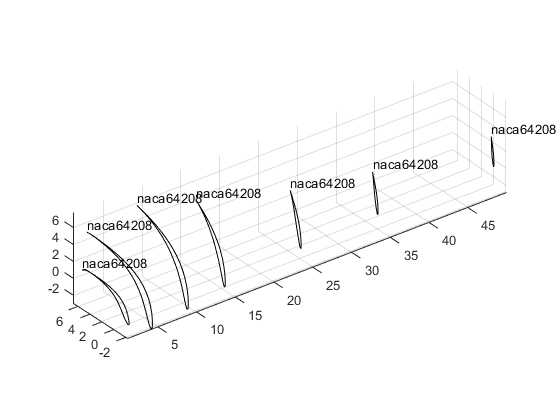

grid on